# Experimental setup with signal sums

Evaluating on different parameter setups with different randomly generated signals

clear all;

signal_params = [
    1, 1, 1, 100, 0;
    10, 1, 1, 100, 0;
    1, 100, 1, 100, 0;
    10, 100, 1, 100, 0;
    1, 1, 1, 100, 0.1;
    10, 1, 1, 100, 0.1;
    1, 100, 1, 100, 0.1;
    10, 100, 1, 100, 0.1;
    1, 1, 1, 100, 0.5;
    10, 1, 1, 100, 0.5;
    1, 100, 1, 100, 0.5;
    10, 100, 1, 100, 0.5;
    1, 1, 1, 200, 0;
    10, 1, 1, 200, 0;
    1, 100, 1, 200, 0;
    10, 100, 1, 200, 0;
    1, 1, 1, 200, 0.1;
    10, 1, 1, 200, 0.1;
    1, 100, 1, 200, 0.1;
    10, 100, 1, 200, 0.1;
    1, 1, 1, 200, 0.5;
    10, 1, 1, 200, 0.5;
    1, 100, 1, 200, 0.5;
    10, 100, 1, 200, 0.5
];

x = signal_params(1:12,:)

x = 1.0e+02 *

   0.010000000000000   0.010000000000000   0.010000000000000   1.000000000000000                   0
   0.100000000000000   0.010000000000000   0.010000000000000   1.000000000000000                   0
   0.010000000000000   1.000000000000000   0.010000000000000   1.000000000000000                   0
   0.100000000000000   1.000000000000000   0.010000000000000   1.000000000000000                   0
   0.010000000000000   0.010000000000000   0.010000000000000   1.000000000000000   0.001000000000000
   0.100000000000000   0.010000000000000   0.010000000000000   1.000000000000000   0.001000000000000
   0.010000000000000   1.000000000000000   0.010000000000000   1.000000000000000   0.001000000000000
   0.100000000000000   1.000000000000000   0.010000000000000   1.000000000000000   0.001000000000000
   0.010000000000000   0.010000000000000   0.010000000000000   1.000000000000000   0.005000000000000
   0.100000000000000   0.010000000000000   0.010000000000000   1.00000000000

num_experiments = 1;
max_signals = 1;

%assuming you want to predict 5 in the future

## Generate Hankel and Seg/Dec experimental dimensions for tensors

vector = (1:100);
dim_range = 2:100;
dimsSD = generate_sddim(vector,dim_range,0);
dimsSDm = dimsSD(dimsSD(:,3)==1,:);
dim_range = 10:10:100;
dimsH = generate_hankeldim(vector,dim_range);
length(dimsH)

ans =     45


## 1. Hankel matrix dimensions experiments

[ex1bestL, ex1gt1mean, ex1gt2mean] = ar_ex_matrix(signal_params(1:12,:),(5:5:100)',max_signals,num_experiments);

Testing L value 5
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 10
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 15
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 20
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 25
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 30
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 35
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 40
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 45
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 50
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 55
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 60
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 65
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 70
Parameter simulation 1/12
Generat

## 2. Segmented matrix dimensions experiments

[ex2bestL, ex2gt1mean, ex2gt2mean] = ar_ex_matrix(signal_params(1:12,:),dimsSDm(:,1),max_signals,num_experiments,'embedding', 2);

Testing L value 2
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 4
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 5
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 10
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 20
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 25
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 50
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing L value 2
Parameter simulation 2/12
Generated signal 1/1
iter 1
Testing L value 4
Parameter simulation 2/12
Generated signal 1/1
iter 1
Testing L value 5
Parameter simulation 2/12
Generated signal 1/1
iter 1
Testing L value 10
Parameter simulation 2/12
Generated signal 1/1
iter 1
Testing L value 20
Parameter simulation 2/12
Generated signal 1/1
iter 1
Testing L value 25
Parameter simulation 2/12
Generated signal 1/1
iter 1
Testing L value 50
Parameter simulation 2/12
Generated si

## 3. Decimated matrix dimensions experiments

[ex3bestL, ex3gt1mean, ex3gt2mean] = ar_ex_matrix(signal_params(1:12,:),dimsSDm(:,1),max_signals,num_experiments,'embedding', 3);

Testing L value 2
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing L value 4
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing L value 5
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing L value 10
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing L value 20
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing L value 25
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing L value 50
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing L value 2
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing L value 4
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing L value 5
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing L value 10
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing L value 20
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing L value 25
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing L value 50
Parameter simulation 2/4
Generated signal 1/1
iter 

## 4. Hankel tensor dimensions experiments

[ex4bestLM, ex4gt1mean, ex4gt2mean] = ar_ex_tensor(signal_params(1:12,:),dimsH(1:10,:),max_signals,num_experiments);

Testing dimensions values: 10x10x82
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing dimensions values: 10x20x72
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing dimensions values: 10x30x62
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing dimensions values: 10x40x52
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing dimensions values: 10x50x42
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing dimensions values: 10x60x32
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing dimensions values: 10x70x22
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing dimensions values: 10x80x12
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing dimensions values: 10x90x2
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing dimensions values: 20x10x72
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing dimensions values: 10x10x82
Parameter simulation 2/12
Generated signal 1/1
iter 1
Testing dim

## 5. Segmented tensor dimensions experiments

[ex5bestLM, ex5gt1mean, ex5gt2mean] = ar_ex_tensor(signal_params(1:4,:),dimsSD(1:2,:),max_signals,num_experiments,'embedding', 2);

Testing dimensions values: 2x2x25
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing dimensions values: 2x5x10
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing dimensions values: 2x2x25
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing dimensions values: 2x5x10
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing dimensions values: 2x2x25
Parameter simulation 3/4
Generated signal 1/1
iter 1
Testing dimensions values: 2x5x10
Parameter simulation 3/4
Generated signal 1/1
iter 1
Testing dimensions values: 2x2x25
Parameter simulation 4/4
Generated signal 1/1
iter 1
Testing dimensions values: 2x5x10
Parameter simulation 4/4
Generated signal 1/1
iter 1
Done!


## 6. Decimated tensor dimensions experiments

[ex6bestLM, ex6gt1mean, ex6gt2mean] = ar_ex_tensor(signal_params(1:12,:),dimsSD(1:2,:),max_signals,num_experiments,'embedding', 3);

Testing dimensions values: 2x2x25
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing dimensions values: 2x5x10
Parameter simulation 1/12
Generated signal 1/1
iter 1
Testing dimensions values: 2x2x25
Parameter simulation 2/12
Generated signal 1/1
iter 1
Testing dimensions values: 2x5x10
Parameter simulation 2/12
Generated signal 1/1
iter 1
Testing dimensions values: 2x2x25
Parameter simulation 3/12
Generated signal 1/1
iter 1
Testing dimensions values: 2x5x10
Parameter simulation 3/12
Generated signal 1/1
iter 1
Testing dimensions values: 2x2x25
Parameter simulation 4/12
Generated signal 1/1
iter 1
Testing dimensions values: 2x5x10
Parameter simulation 4/12
Generated signal 1/1
iter 1
Testing dimensions values: 2x2x25
Parameter simulation 5/12
Generated signal 1/1
iter 1
Testing dimensions values: 2x5x10
Parameter simulation 5/12
Generated signal 1/1
iter 1
Testing dimensions values: 2x2x25
Parameter simulation 6/12
Generated signal 1/1
iter 1
Testing dimensions values: 2x5x1

## What is the best dimension? 

Lets plot the dimensions

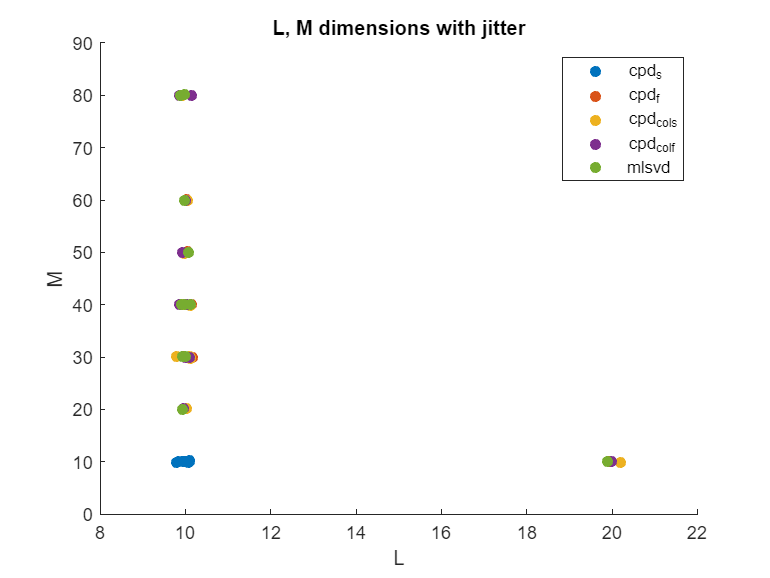

% Get field names
fields = fieldnames(ex4bestLM);

% Create a new figure
figure;
hold on;

% Define a set of colors or markers for different fields
colors = lines(length(fields)); % Using lines colormap for distinct colors
jitterAmount = 0.1;

% Iterate over each field and plot the matrices
for i = 1:length(fields)
    matrix = ex4bestLM.(fields{i});
    x = matrix(:, 1) + jitterAmount * randn(size(matrix, 1), 1);
    y = matrix(:, 2) + jitterAmount * randn(size(matrix, 1), 1);
    scatter(x, y, [], colors(i,:), 'filled', 'DisplayName', fields{i}); % Using colors for distinction
end
hold on;

% Label the plot
xlabel('L');
ylabel('M');
title('L, M dimensions with jitter');
legend show;

We have the following algorithm:

- Select the most common or median-closest values for our L,M pairs.

- For single-column matrices, it identifies the most common value.

- For multi-column matrices, it considers both columns, accounts for ties, and ensures the final selected values are the most representative of the L, M pairs.

best_dimensions_hankel = zeros(6,2);
best_dimensions_hankel(1,1) = bestL(ex1bestL.SVD(:));
for i = 1:length(fields)
    matrix = ex4bestLM.(fields{i});
    best_dimensions_hankel(i+1,:) = bestLM(matrix);
end

And do the same for the other embeddings

best_dimensions_segment = zeros(6,2);
best_dimensions_segment(1,1) = bestL(ex2bestL.SVD(:));
for i = 1:length(fields)
    matrix = ex5bestLM.(fields{i});
    best_dimensions_segment(i+1,:) = bestLM(matrix);
end

best_dimensions_decimate = zeros(6,2);
best_dimensions_decimate(1,1) = bestL(ex3bestL.SVD(:));
for i = 1:length(fields)
    matrix = ex6bestLM.(fields{i});
    best_dimensions_decimate(i+1,:) = bestLM(matrix);
end

## 7.1 Component number experiments - Hankel

[ex71comp, ex71gt1mean, ex71gt2mean] = ar_ex_comp(signal_params(1:4,:),max_signals,num_experiments,best_dimensions_hankel,1:3,'embedding', 1);

Testing 1 number of components
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing 2 number of components
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing 3 number of components
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing 1 number of components
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing 2 number of components
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing 3 number of components
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing 1 number of components
Parameter simulation 3/4
Generated signal 1/1
iter 1
Testing 2 number of components
Parameter simulation 3/4
Generated signal 1/1
iter 1
Testing 3 number of components
Parameter simulation 3/4
Generated signal 1/1
iter 1
Testing 1 number of components
Parameter simulation 4/4
Generated signal 1/1
iter 1
Testing 2 number of components
Parameter simulation 4/4
Generated signal 1/1
iter 1
Testing 3 number of components
Parameter simulation 4/4
Generated signal 1/1

## 7.2 Component number experiments - Segmentation

[ex72comp, ex72gt1mean, ex72gt2mean] = ar_ex_comp(signal_params(1:4,:),max_signals,num_experiments,best_dimensions_segment,1:3,'embedding', 2);

Testing 1 number of components
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing 2 number of components
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing 3 number of components
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing 1 number of components
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing 2 number of components
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing 3 number of components
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing 1 number of components
Parameter simulation 3/4
Generated signal 1/1
iter 1
Testing 2 number of components
Parameter simulation 3/4
Generated signal 1/1
iter 1
Testing 3 number of components
Parameter simulation 3/4
Generated signal 1/1
iter 1
Testing 1 number of components
Parameter simulation 4/4
Generated signal 1/1
iter 1
Testing 2 number of components
Parameter simulation 4/4
Generated signal 1/1
iter 1
Testing 3 number of components
Parameter simulation 4/4
Generated signal 1/1

## 7.3 Component number experiments - Decimation

[ex73comp, ex73gt1mean, ex73gt2mean] = ar_ex_comp(signal_params(1:4,:),max_signals,num_experiments,best_dimensions_segment,1:3,'embedding', 3);

Testing 1 number of components
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing 2 number of components
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing 3 number of components
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing 1 number of components
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing 2 number of components
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing 3 number of components
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing 1 number of components
Parameter simulation 3/4
Generated signal 1/1
iter 1
Testing 2 number of components
Parameter simulation 3/4
Generated signal 1/1
iter 1
Testing 3 number of components
Parameter simulation 3/4
Generated signal 1/1
iter 1
Testing 1 number of components
Parameter simulation 4/4
Generated signal 1/1
iter 1
Testing 2 number of components
Parameter simulation 4/4
Generated signal 1/1
iter 1
Testing 3 number of components
Parameter simulation 4/4
Generated signal 1/1

## 8.1 Threshold experiments - Hankel

[ex81threshold, ex81gt1mean, ex81gt2mean] = ar_ex_threshold(signal_params(1:4,:),max_signals,num_experiments,best_dimensions_hankel,0.001:0.01:0.1, 'embedding', 1);

Testing threshold value: 0.0
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.0
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.0
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.0
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.0
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.1
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.1
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.1
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.1
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.1
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.0
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing threshold value: 0.0
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing threshol

## 8.2 Threshold experiments - Segmentation

[ex82threshold, ex82gt1mean, ex82gt2mean] =  ar_ex_threshold(signal_params(1:4,:),max_signals,num_experiments,best_dimensions_segment,0.001:0.01:0.1, 'embedding', 2);

Testing threshold value: 0.0
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.0
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.0
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.0
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.0
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.1
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.1
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.1
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.1
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.1
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.0
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing threshold value: 0.0
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing threshol

## 8.3 Threshold experiments - Decimation

[ex83threshold, ex83gt1mean, ex83gt2mean] = ar_ex_threshold(signal_params(1:4,:),max_signals,num_experiments,best_dimensions_decimate,0.001:0.01:0.1, 'embedding', 3);

Testing threshold value: 0.0
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.0
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.0
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.0
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.0
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.1
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.1
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.1
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.1
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.1
Parameter simulation 1/4
Generated signal 1/1
iter 1
Testing threshold value: 0.0
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing threshold value: 0.0
Parameter simulation 2/4
Generated signal 1/1
iter 1
Testing threshol

For determining the best component number and threshold value, we use the same heuristic as for calculating the best L.

fields = fieldnames(ex71comp);

best_comp_hankel = zeros(length(fields),1);

for i = 1:length(fields)
    vec = ex71comp.(fields{i})';
    best_comp_hankel(i) = bestL(vec);
end

best_comp_segment = zeros(length(fields),1);

for i = 1:length(fields)
    vec = ex72comp.(fields{i})';
    best_comp_segment(i) = bestL(vec);
end

best_comp_decimate = zeros(length(fields),1);

for i = 1:length(fields)
    vec = ex73comp.(fields{i})';
    best_comp_decimate(i) = bestL(vec);
end

fields = fieldnames(ex81threshold);

best_thresh_hankel = zeros(length(fields),1);

for i = 1:length(fields)
    vec = ex81threshold.(fields{i})';
    best_thresh_hankel(i) = bestL(vec);
end

best_thresh_segment = zeros(length(fields),1);

for i = 1:length(fields)
    vec = ex82threshold.(fields{i})';
    best_thresh_segment(i) = bestL(vec);
end

best_thresh_decimate = zeros(length(fields),1);

for i = 1:length(fields)
    vec = ex83threshold.(fields{i})';
    best_thresh_decimate(i) = bestL(vec);
end


## 9. Performance of optimal parameter for each model Hankel - mean

[ex9gt1mean, ex9gt2mean] = ar_ex_perform(signal_params(1:4,:),max_signals,num_experiments,best_dimensions_hankel,'num_components', best_comp_hankel,'threshold', best_thresh_hankel,'embedding', 1);

Parameter simulation 1/4
Generated signal 1/1
iter 1
Parameter simulation 2/4
Generated signal 1/1
iter 1
Parameter simulation 3/4
Generated signal 1/1
iter 1
Parameter simulation 4/4
Generated signal 1/1
iter 1
Done!


## 10. Performance of optimal parameter for each model Hankel - median

[ex10gt1mean, ex10gt2mean] = ar_ex_perform(signal_params(1:4,:),max_signals,num_experiments,best_dimensions_hankel,'num_components', best_comp_hankel,'threshold', best_thresh_hankel,'embedding', 1,'Method', 'median');

Parameter simulation 1/4
Generated signal 1/1
iter 1
Parameter simulation 2/4
Generated signal 1/1
iter 1
Parameter simulation 3/4
Generated signal 1/1
iter 1
Parameter simulation 4/4
Generated signal 1/1
iter 1
Done!


## 11. Performance of optimal parameter for each model Segmentation - mean

[ex11gt1mean, ex11gt2mean] = ar_ex_perform(signal_params(1:4,:),max_signals,num_experiments,best_dimensions_segment,'num_components', best_comp_segment,'threshold', best_thresh_segment,'embedding', 2);

Parameter simulation 1/4
Generated signal 1/1
iter 1
Parameter simulation 2/4
Generated signal 1/1
iter 1
Parameter simulation 3/4
Generated signal 1/1
iter 1
Parameter simulation 4/4
Generated signal 1/1
iter 1
Done!


## 12. Performance of optimal parameter for each model Segmentation - median

[ex12gt1mean, ex12gt2mean] = ar_ex_perform(signal_params(1:4,:),max_signals,num_experiments,best_dimensions_segment,'num_components', best_comp_segment,'threshold', best_thresh_segment,'embedding', 2,'Method', 'median');

Parameter simulation 1/4
Generated signal 1/1
iter 1
Parameter simulation 2/4
Generated signal 1/1
iter 1
Parameter simulation 3/4
Generated signal 1/1
iter 1
Parameter simulation 4/4
Generated signal 1/1
iter 1
Done!


## 13. Performance of optimal parameter for each model Decimation - mean

[ex13gt1mean, ex13gt2mean] = ar_ex_perform(signal_params(1:4,:),max_signals,num_experiments,best_dimensions_decimate,'num_components', best_comp_decimate,'threshold', best_thresh_decimate,'embedding', 3);

Parameter simulation 1/4
Generated signal 1/1
iter 1
Parameter simulation 2/4
Generated signal 1/1
iter 1
Parameter simulation 3/4
Generated signal 1/1
iter 1
Parameter simulation 4/4
Generated signal 1/1
iter 1
Done!


## 14. Performance of optimal parameter for each model Decimation - median

[ex14gt1mean, ex14gt2mean] = ar_ex_perform(signal_params(1:4,:),max_signals,num_experiments,best_dimensions_decimate,'num_components', best_comp_decimate,'threshold', best_thresh_decimate,'embedding', 3,'Method', 'median');

Parameter simulation 1/4
Generated signal 1/1
iter 1
Parameter simulation 2/4
Generated signal 1/1
iter 1
Parameter simulation 3/4
Generated signal 1/1
iter 1
Parameter simulation 4/4
Generated signal 1/1
iter 1
Done!


## 15. Performance using RMSE for multiple points in the future

[ex18gt1mean, ex18gt2mean] = ar_ex_rmse(signal_params(1:12,:),max_signals,num_experiments,best_dimensions_hankel,50,'num_components', best_comp_hankel, 'threshold', best_thresh_hankel);

Parameter simulation 1/12
Generated signal 1/1
iter 1
Parameter simulation 2/12
Generated signal 1/1
iter 1
Parameter simulation 3/12
Generated signal 1/1
iter 1
Parameter simulation 4/12
Generated signal 1/1
iter 1
Parameter simulation 5/12
Generated signal 1/1
iter 1
Parameter simulation 6/12
Generated signal 1/1
iter 1
Parameter simulation 7/12
Generated signal 1/1
iter 1
Parameter simulation 8/12
Generated signal 1/1
iter 1
Parameter simulation 9/12
Generated signal 1/1
iter 1
Parameter simulation 10/12
Generated signal 1/1
iter 1
Parameter simulation 11/12
Generated signal 1/1
iter 1
Parameter simulation 12/12
Generated signal 1/1
iter 1
Done!
